# Chemical Reaction Kinetics: Kinetic Model Estimation from Experimental Data

## Introduction

Characterizing chemical reactions to identify parameters for chemical reaction kinetics involves evaluation of experimental data. The use of MATLAB to import experimental data from a variety of file formats, and to estimate the reaction parameters (reaction rate constant and order of reaction).

To estimate the order of the reaction rate for the reactant and each of the products, it is important to plot the data in a number of ways to identify key characteristics. For more details, please refer to

- A plot of ln C vs. time - If this plot is linear, this indicates a 1st order reaction

- A plot of 1/C vs. time - If this plot is linear, this indicates a 2nd order reaction

## Exercise: Decomposition of nitrogen dioxide

Experimental data for the decomposition of $NO_2$ is given in '`reactiondata.xlsx`'. The Time values are in $s$, and the concentrations for each compound is expressed in $\textrm{mol}/L$.


$$2\;NO_2 \;\longrightarrow 2\;\textrm{NO}+O_2$$


Estimate the reaction order and rate constant $k$for the reactant $NO_2$.

### Step 1: Import experimental data

% Import data from spreadsheet
reactiondata = readtable("/MATLAB Drive/EuroVarietyMATLAB/reactiondata.xlsx");

% Display results
reactiondata

reactiondata = 9×4 table
    Time     NO2        NO        O2  
    ____    ______    ______    ______

      0       0.01         0         0
     50     0.0079    0.0021    0.0011
    100     0.0065    0.0035    0.0018
    150     0.0055    0.0045    0.0023
    200     0.0048    0.0052    0.0026
    250     0.0043    0.0057    0.0029
    300     0.0038    0.0062    0.0031
    350     0.0034    0.0066    0.0033
    400     0.0031    0.0069    0.0035


### Step 2: Visualize the rate of the reaction

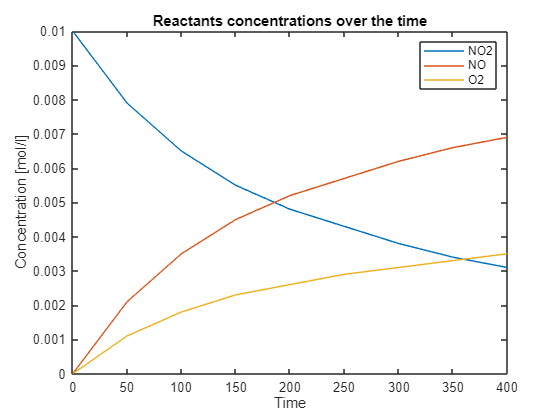

f = figure;
% Create plot of reactiondata.Time and reactiondata.NO2
plot(reactiondata,"Time","NO2","DisplayName","NO2");

hold on
% Create plot of reactiondata.Time and reactiondata.NO
plot(reactiondata,"Time","NO","DisplayName","NO");
% Create plot of reactiondata.Time and reactiondata.O2
plot(reactiondata,"Time","O2","DisplayName","O2");
hold off

legend

title("Reactants concentrations over the time")
ylabel("Concentration [mol/l]")

It can be observed that the concentration of $NO_2$, as expected for a reactant, reduces over time and that of $NO$ and $O_2$, the products, increase over time in keeping with their reaction laws.

### Step 3: Assume the First Order Kinetics

#### Convert data to plot linearized form

Let the ${\textrm{NO}}_2$ concentration will be expressed as cNO2 variable

cNO2 = reactiondata.NO2;

Transform the data by using mathematical operation to prepare it to the first-order-like linearized form

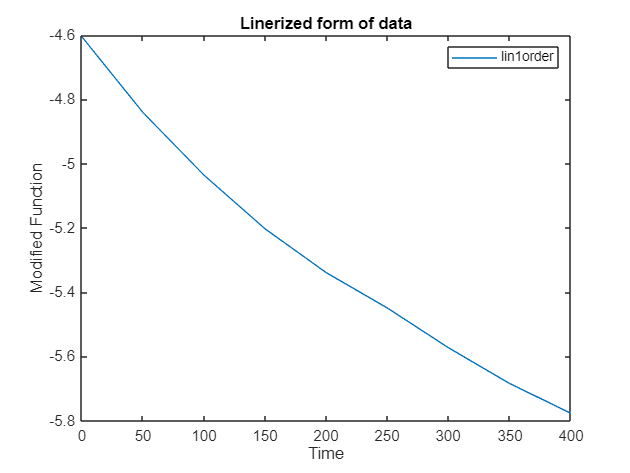

lin1order = log(cNO2);
% Create plot of reactiondata.Time and lin1order
h2 = plot(reactiondata.Time,lin1order,"DisplayName","lin1order");

% Add xlabel, ylabel, title, and legend
xlabel("Time")
ylabel("Modified Function")
title("Linerized form of data")
legend

#### Fit the line and add the outcoming plot

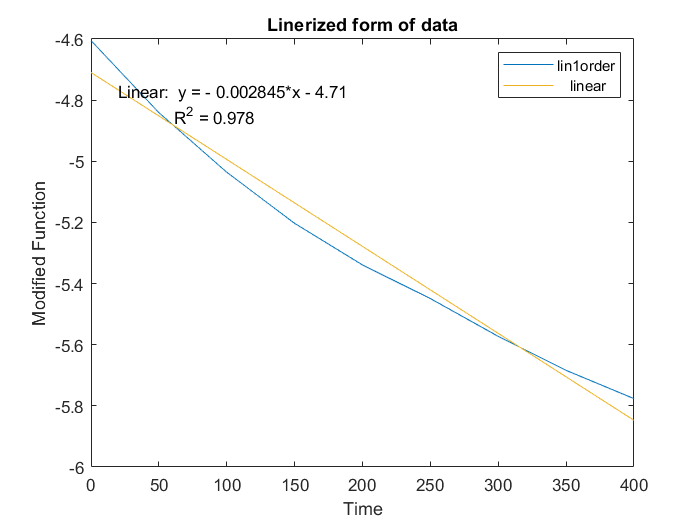

### Step 4: Assume the scond order kinetics form

Handle with data by using Curve Fitting App. Try to fit the second order kinetic equation form and determine values of constants

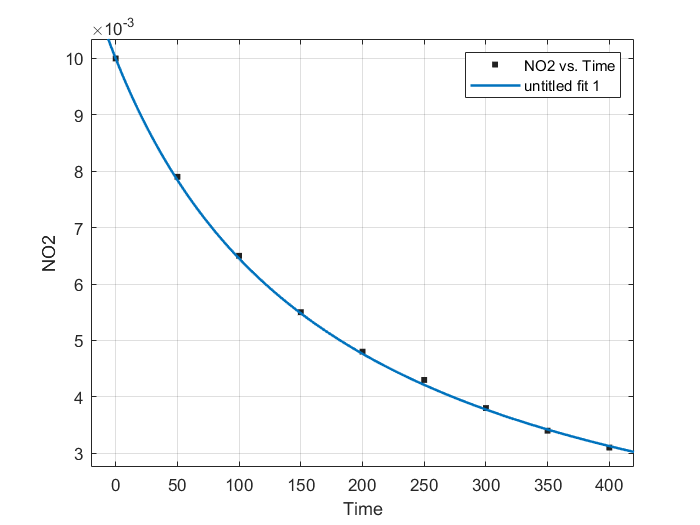

concentration=secondOrderModel

concentration =      General model:
     concentration(x) = 1e-2/(1e-2*k*x+1)
     Coefficients (with 95% confidence bounds):
       k =      0.5497  (0.5408, 0.5587)

The k is shown in the figure above.

### Step 5: Publish and share

This interactive document can be saved into PDF or HTML formats for dissemination outside the MATLAB environment.

 Copyright 2016 - 2017 The MathWorks, Inc.